t = readtable("10Ax1.tsv", "FileType","text",'Delimiter', '\t');

t.EMRX

ans = 1.0e+03 *

    0.7520
    0.7502
    0.7432
    0.7416
    0.7403
    0.7392
    0.7379
    0.7420
    0.7406
    0.7392


EMR = [t.EMRX(1), t.EMRY(1), t.EMRZ(1)] 

EMR = 1.0e+03 *

    0.7520    0.4443    1.9348


PMR = [t.PMRX(1), t.PMRY(1), t.PMRZ(1)] % US (ulnar styloid)

PMR = 1.0e+03 *

    1.0456    0.2339    2.2038


ELR = [t.ELRX(1), t.ELRY(1), t.ELRZ(1)]

ELR = 1.0e+03 *

    0.6702    0.3685    2.0394


PLR = [t.PLRX(1), t.PLRY(1), t.PLRZ(1)] % RS (radial styloid)

PLR = 1.0e+03 *

    1.0336    0.1641    2.1823



Mid_EP = (ELR + EMR) / 2;  % Midpoint of the epicondyles

% X_f axis is perpendicular to the plane formed by
% PMR, PLR and Mid_EP
v_1 = PLR - PMR;
v_2 = Mid_EP - PMR;
X_f = cross(v_1, v_2);
X_f = X_f / norm(X_f);

% Y_f axis is the unit vector from US (PMR) to Mid_EP
Y_f = Mid_EP - PMR;
Y_f = Y_f / norm(Y_f);

% Z_f is perpendicular to X_f and Y_f
Z_f = cross(X_f, Y_f);
Z_f = Z_f / norm(Z_f);

% The attitude matrix
F_forearm = [X_f', Y_f', Z_f']

F =     0.5893   -0.7702    0.2439
    0.1440    0.3972    0.9064
   -0.7949   -0.4990    0.3450


Norm of X_f:
     1



Norm of Y_f:
     1



Norm of Z_f:
     1



Dot product X_f ⋅ Y_f:
     0



Dot product X_f ⋅ Z_f:
     0



Dot product Y_f ⋅ Z_f:
  -2.7756e-17



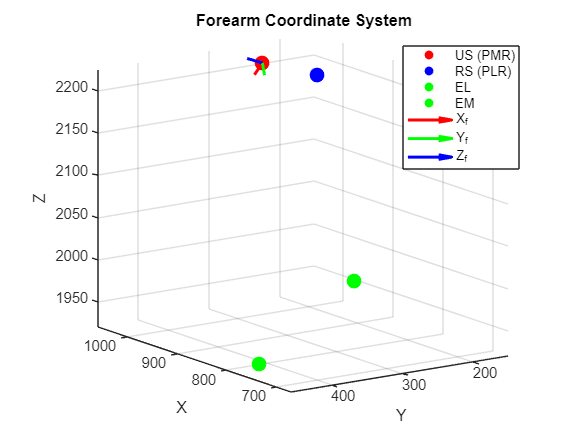


figure;
hold on; grid on; axis equal;

% Scale factor for the axes to make them more visible
scale_factor = 20;

% Plot the key points
scatter3(PMR(1), PMR(2), PMR(3), 100, 'r', 'filled'); % US (PMR)
scatter3(PLR(1), PLR(2), PLR(3), 100, 'b', 'filled'); % RS (PLR)
scatter3(ELR(1), ELR(2), ELR(3), 100, 'g', 'filled'); % EL
scatter3(EMR(1), EMR(2), EMR(3), 100, 'g', 'filled'); % EM

% Draw scaled axes
quiver3(PMR(1), PMR(2), PMR(3), X_f(1)*scale_factor, X_f(2)*scale_factor, X_f(3)*scale_factor, 0, 'r', 'LineWidth', 2); % X_f in red
quiver3(PMR(1), PMR(2), PMR(3), Y_f(1)*scale_factor, Y_f(2)*scale_factor, Y_f(3)*scale_factor, 0, 'g', 'LineWidth', 2); % Y_f in green
quiver3(PMR(1), PMR(2), PMR(3), Z_f(1)*scale_factor, Z_f(2)*scale_factor, Z_f(3)*scale_factor, 0, 'b', 'LineWidth', 2); % Z_f in blue

% Labels
legend('US (PMR)', 'RS (PLR)', 'EL', 'EM', 'X_f', 'Y_f', 'Z_f');
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Forearm Coordinate System');
view(3); % 3D view
hold off;